# Hand Gesture Recognition CNN with Enhanced Techniques

clc; clear; close all;


## Step 1: Load Dataset

disp("1) Loading HandGestures dataset...");

1) Loading HandGestures dataset...


imds = imageDatastore('HandGestures', ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

disp("   Class Distribution:");

   Class Distribution:


disp(countEachLabel(imds));

      Label      Count
    _________    _____

    Fist         1000 
    Heart        1000 
    Okay         1000 
    Peace        1000 
    Thumbs_Up    1000 



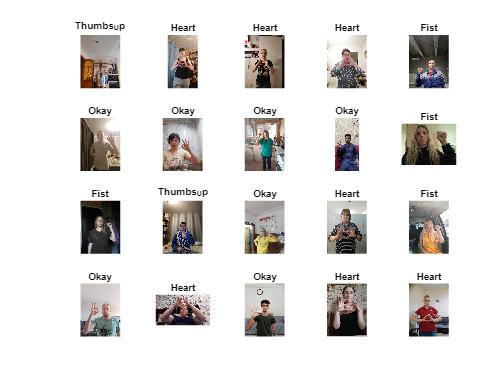


% Display 20 random samples
figure('Name','Sample Images','NumberTitle','off');
perm = randperm(numel(imds.Files),20);
for i = 1:20
    subplot(4,5,i);
    imshow(readimage(imds,perm(i)));
    title(string(imds.Labels(perm(i))),'FontSize',8);
end

## Step 2: Split Dataset (80% Train / 20% Val)

[trainImgs,valImgs] = splitEachLabel(imds,0.8,'randomized');
disp("2) Split into training & validation sets.");

2) Split into training & validation sets.


## Step 3: Load Pretrained ResNet18

disp("3) Loading ResNet-18...");

3) Loading ResNet-18...


net = resnet18;
inputSize = net.Layers(1).InputSize;   % typically [224 224 3]


## Step 4: Strong Data Augmentation (fixed)

disp("4) Configuring data augmentation...");

4) Configuring data augmentation...


augmenter = imageDataAugmenter( ...
    'RandRotation',[-30 30], ...
    'RandXTranslation',[-15 15], ...
    'RandYTranslation',[-15 15], ...
    'RandXScale',[0.7 1.3], ...
    'RandYScale',[0.7 1.3], ...
    'RandXShear',[-20 20], ...
    'RandYShear',[-20 20], ...
    'RandXReflection',true);

augTrain = augmentedImageDatastore( ...
    inputSize(1:2), ...                  % resize to network input
    trainImgs, ...                       % your training datastore
    'DataAugmentation', augmenter, ...
    'DispatchInBackground', true);       % enable background workers

augVal   = augmentedImageDatastore(inputSize(1:2), valImgs);  % no augmentation


## Step 5: Modify Final Layers + Freeze Early Layers + Class Weights

disp("5) Customizing network layers...");

5) Customizing network layers...



lgraph = layerGraph(net);

% Remove original classification layers
lgraph = removeLayers(lgraph,{'fc1000','prob','ClassificationLayer_predictions'});

% Compute per-class weights to handle imbalance
tbl = countEachLabel(trainImgs);
classWeights = max(tbl.Count)./tbl.Count;
classNames   = tbl.Label;
numClasses   = numel(classNames);

% Define new classification layers with weight factors
newLayers = [
    fullyConnectedLayer(numClasses,'Name','fc_new', ...
        'WeightLearnRateFactor',10,'BiasLearnRateFactor',10)
    softmaxLayer('Name','softmax_new')
    classificationLayer('Name','classoutput', ...
        'Classes',classNames, ...
        'ClassWeights',classWeights)
];
lgraph = addLayers(lgraph,newLayers);
lgraph = connectLayers(lgraph,'pool5','fc_new');  % ResNet-18 uses 'pool5'

% Freeze the first N layers (to speed up & regularize)
layers = lgraph.Layers;
connections = lgraph.Connections;
fiftyLayerIndex = 50; freezeUpTo =  fiftyLayerIndex; % freeze first 50 layers (you can adjust)
for i = 1:freezeUpTo
    if isprop(layers(i),'WeightLearnRateFactor')
        layers(i).WeightLearnRateFactor = 0;
        layers(i).BiasLearnRateFactor   = 0;
    end
end

% 1) Turn your pretrained net into a graph
lgraph = layerGraph(net);

% 2) Remove the old classification layers
lgraph = removeLayers(lgraph,{'fc1000','prob','ClassificationLayer_predictions'});

% 3) Define your new classification layers
numClasses = numel(categories(trainImgs.Labels));
newLayers = [
    fullyConnectedLayer(numClasses,'Name','new_fc', ...
                        'WeightLearnRateFactor',10,'BiasLearnRateFactor',10)
    softmaxLayer('Name','new_softmax')
    classificationLayer('Name','new_output')];

% 4) Add them into the graph
lgraph = addLayers(lgraph,newLayers);

% 5) Wire them up to the end of ResNet‑18’s feature extractor
%    in ResNet‑18 the last pooling layer is 'pool5' (aka 'pool5')
lgraph = connectLayers(lgraph,'pool5','new_fc');


% Optional: visualize final graph once
% analyzeNetwork(lgraph);


## Step 6: Training Options (+ L2 Weight Decay)

disp("6) Setting training options...");

6) Setting training options...


options = trainingOptions('adam', ...
    'InitialLearnRate',5e-5, ...
    'MaxEpochs',20, ...
    'MiniBatchSize',64, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augVal, ...
    'ValidationFrequency',100, ...
    'ValidationPatience',4, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',5, ...
    'LearnRateDropFactor',0.5, ...
    'L2Regularization',1e-4, ...       % weight decay
    'Verbose',false, ...
    'Plots','training-progress', ...
    'ExecutionEnvironment','auto');


## Step 7: Train Network (if needed)

% If you already have 'trainedNet' saved, comment out next two lines!
disp("7) Training network (this may take a while)...");

7) Training network (this may take a while)...


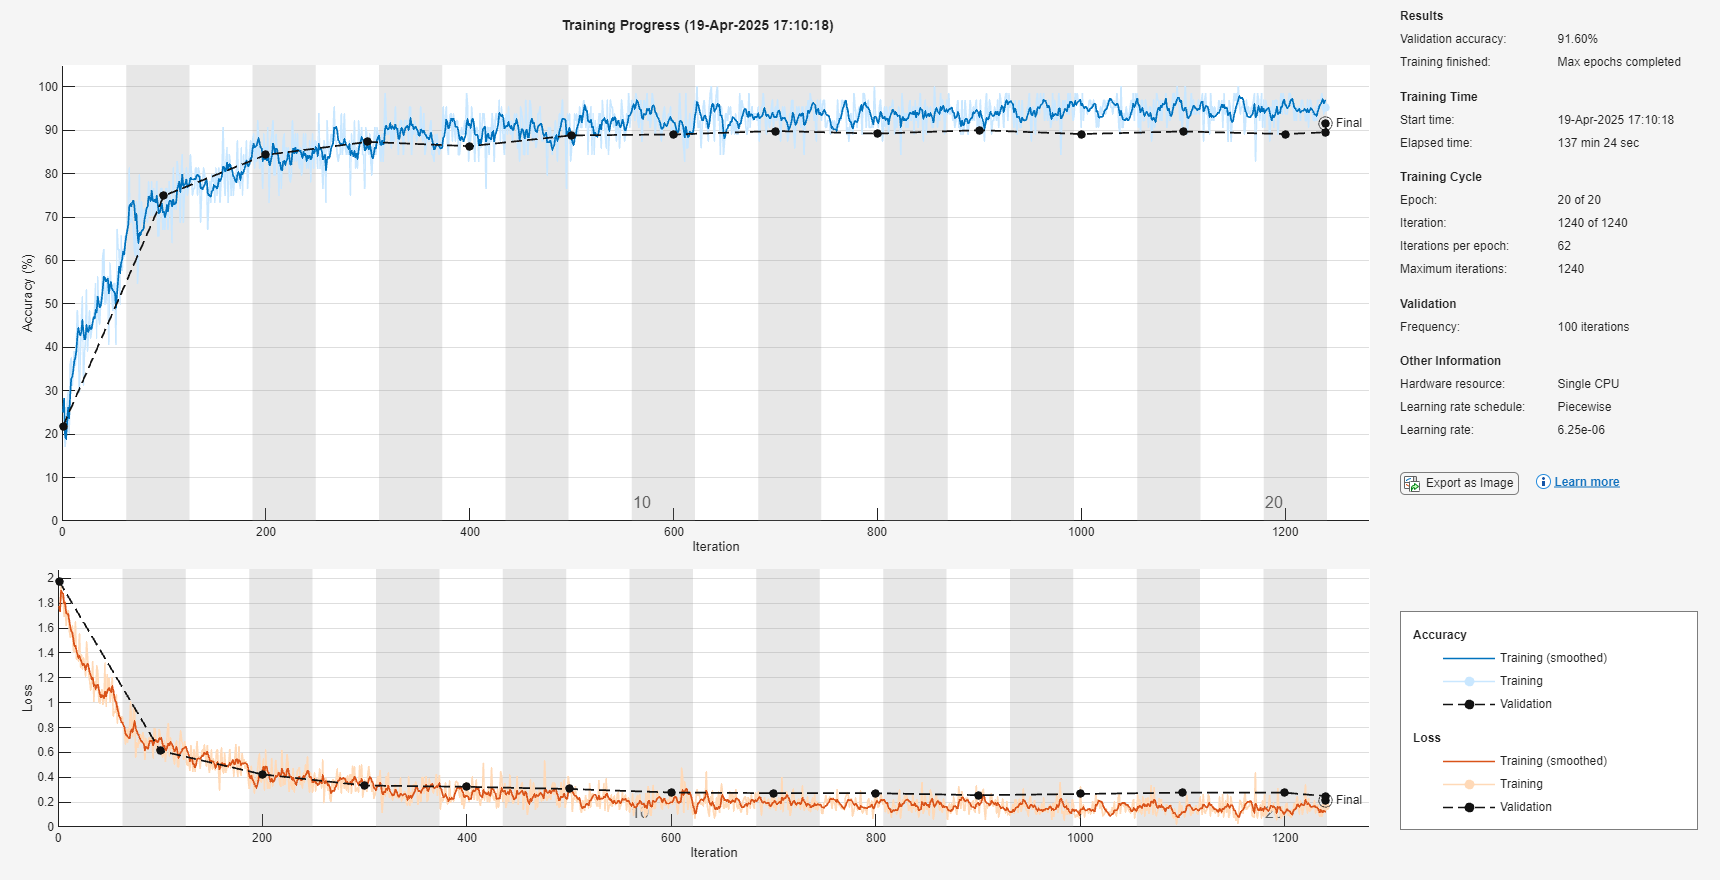

trainedNet = trainNetwork(augTrain,lgraph,options);

disp("   Training complete.");

   Training complete.



% Save for future reuse
save('trainedHandGestureModel_ResNet.mat','trainedNet');


## Step 8: Evaluation on Validation Set

disp("8) Evaluating model...");

8) Evaluating model...



% (a) Classification with Test-Time Augmentation ensemble
function score = TTAclassify(net, img, inputSize)
  % Prepare 4 variants: original, flipped, slight rotation + crop
  variants = {img, fliplr(img), imrotate(img,15,'crop'), imcrop(img,[1 1 inputSize])};
  S = zeros([numel(net.Layers(end).Classes),numel(variants)]);
  for k=1:numel(variants)
    v = imresize(variants{k},inputSize);
    if size(v,3)==1, v = cat(3,v,v,v); end
    [~,s] = classify(net,v);
    S(:,k) = s;
  end
  score = mean(S,2);
end

% Gather scores & predicted labels
scores = zeros(numel(valImgs.Files),numClasses);
for i=1:numel(valImgs.Files)
  I = imread(valImgs.Files{i});
  I = imresize(I,inputSize(1:2));
  scores(i,:) = TTAclassify(trainedNet,I,inputSize(1:2));
end
[~,idx] = max(scores,[],2);
predLabels = classNames(idx);
trueLabels = valImgs.Labels;

% (b) Compute Accuracy
acc = mean(predLabels == trueLabels);
fprintf("   Validation Accuracy: %.2f%%\n",acc*100);

   Validation Accuracy: 92.50%


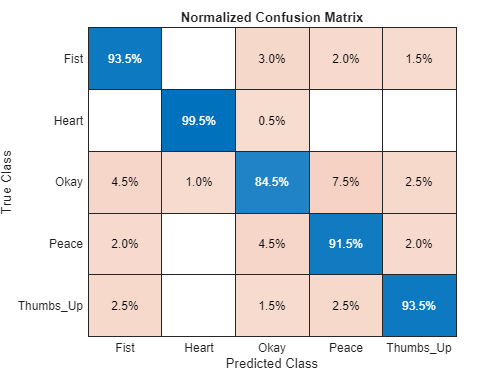


% (c) Confusion Matrix
figure('Name','Confusion Matrix','NumberTitle','off');
confusionchart(trueLabels,predLabels,'Normalization','row-normalized');
title('Normalized Confusion Matrix');


% (d) Precision / Recall / F1
confMat = confusionmat(trueLabels,predLabels);
prec = diag(confMat)./sum(confMat,2);
rec  = diag(confMat)./sum(confMat,1)';
f1   = 2*(prec.*rec)./(prec+rec);
disp("   Per-Class Metrics:");

   Per-Class Metrics:


disp(table(classNames,prec,rec,f1, ...
     'VariableNames',{'Class','Precision','Recall','F1'}));

      Class      Precision    Recall       F1   
    _________    _________    _______    _______

    Fist           0.935       0.9122    0.92346
    Heart          0.995      0.99005    0.99252
    Okay           0.845      0.89894    0.87113
    Peace          0.915      0.88406    0.89926
    Thumbs_Up      0.935       0.9397    0.93734



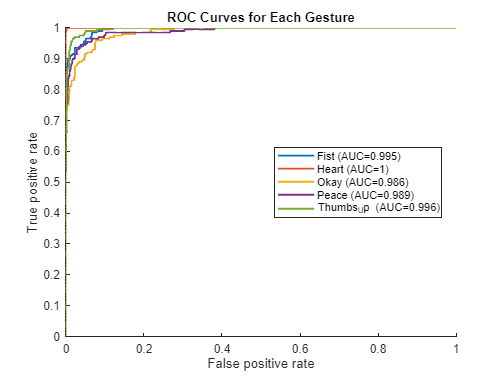


% (e) ROC / AUC Curves
figure('Name','ROC Curves','NumberTitle','off'); hold on;
auc = zeros(numClasses,1);
for c=1:numClasses
  [X,Y,~,auc(c)] = perfcurve(trueLabels,scores(:,c),classNames(c));
  plot(X,Y,'LineWidth',1.5);
end
legend(string(classNames)+" (AUC="+string(round(auc,3))+")",'Location','best');
xlabel('False positive rate'); ylabel('True positive rate');
title('ROC Curves for Each Gesture');



save('TrainedHandGestureModel_Project2', 'trainedNet');
disp("Model saved as 'TrainedHandGestureModel_Project2.mat'");

disp("All done!");

All done!
